## **Simulating Chirp Signal**

**Loading in Data**

% Define file path
folder_path = '/Users/khavishgovind/Library/CloudStorage/OneDrive-UniversityofCapeTown/Masters/CSV_Files';
file_name = 'radar_data_Mipur.mat';
file_path = fullfile(folder_path, file_name);

% Load .mat file
data = load(file_path);
radar_data = data.radar_data;

## *****Matlab is 1 indexing so add 1 to all rows**

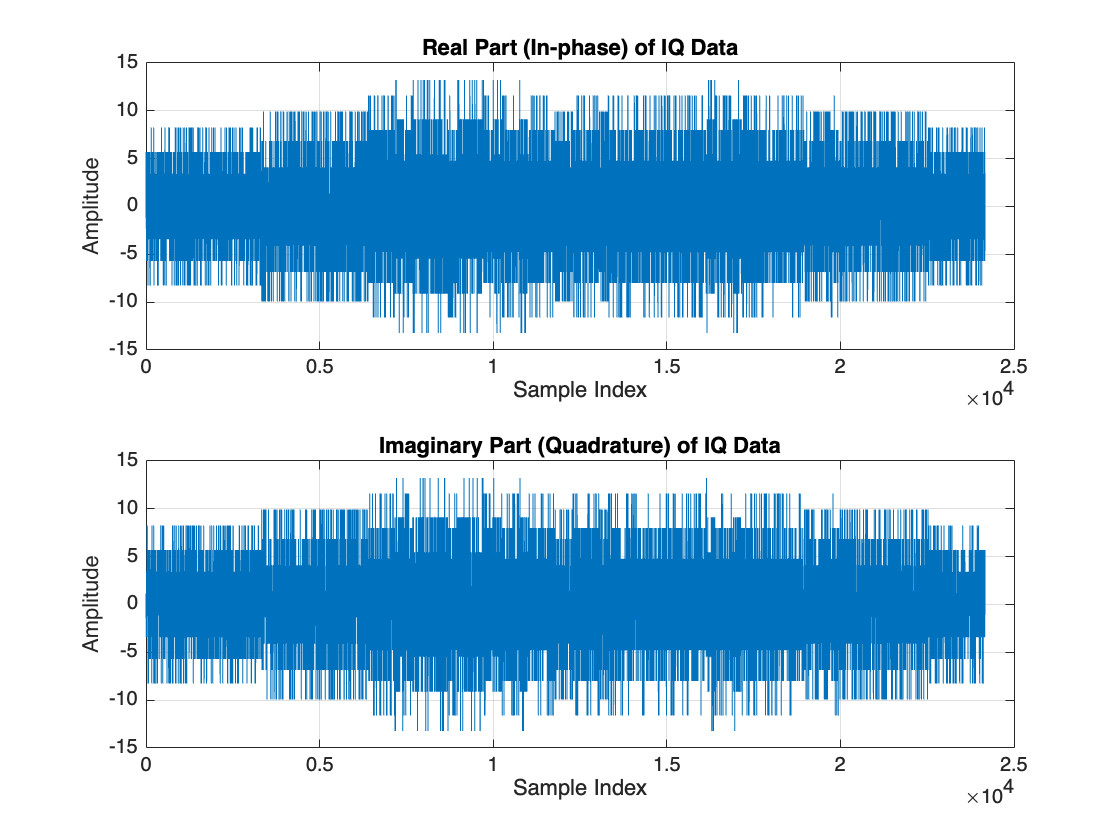

row_idx = 561;  
iq_data = radar_data(row_idx, :); 

% Plot the IQ data
figure;
subplot(2, 1, 1);  
plot(real(iq_data));  
title('Real Part (In-phase) of IQ Data');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(imag(iq_data));  
title('Imaginary Part (Quadrature) of IQ Data');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

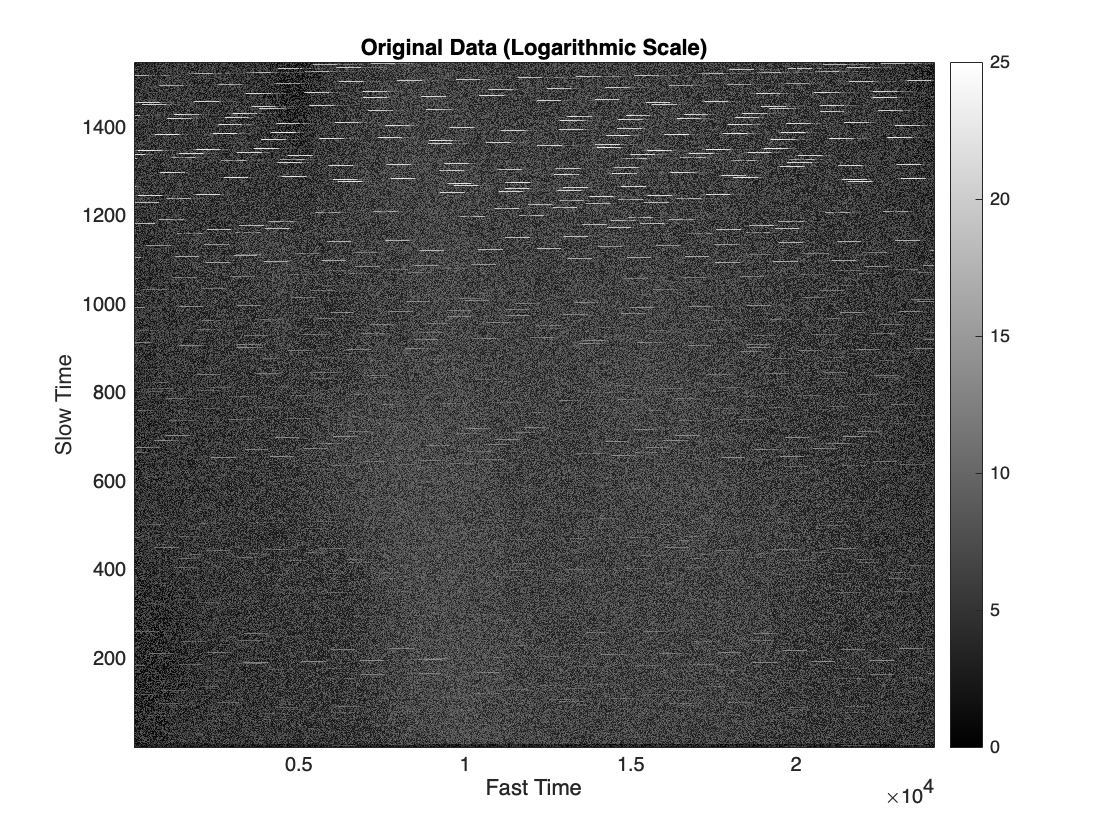

% Magnitude
radar_data_magnitude = abs(radar_data); 
radar_data_log = 10 * log10(radar_data_magnitude + eps); 

% Plot
figure;
imagesc(radar_data_log);  
colormap('gray');  
colorbar;

% Limits
clim([0, 25]); 

% Plot
xlabel('Fast Time');
ylabel('Slow Time');
title('Original Data (Logarithmic Scale)');
axis tight;
axis xy;  
set(gca, 'YDir', 'normal');  

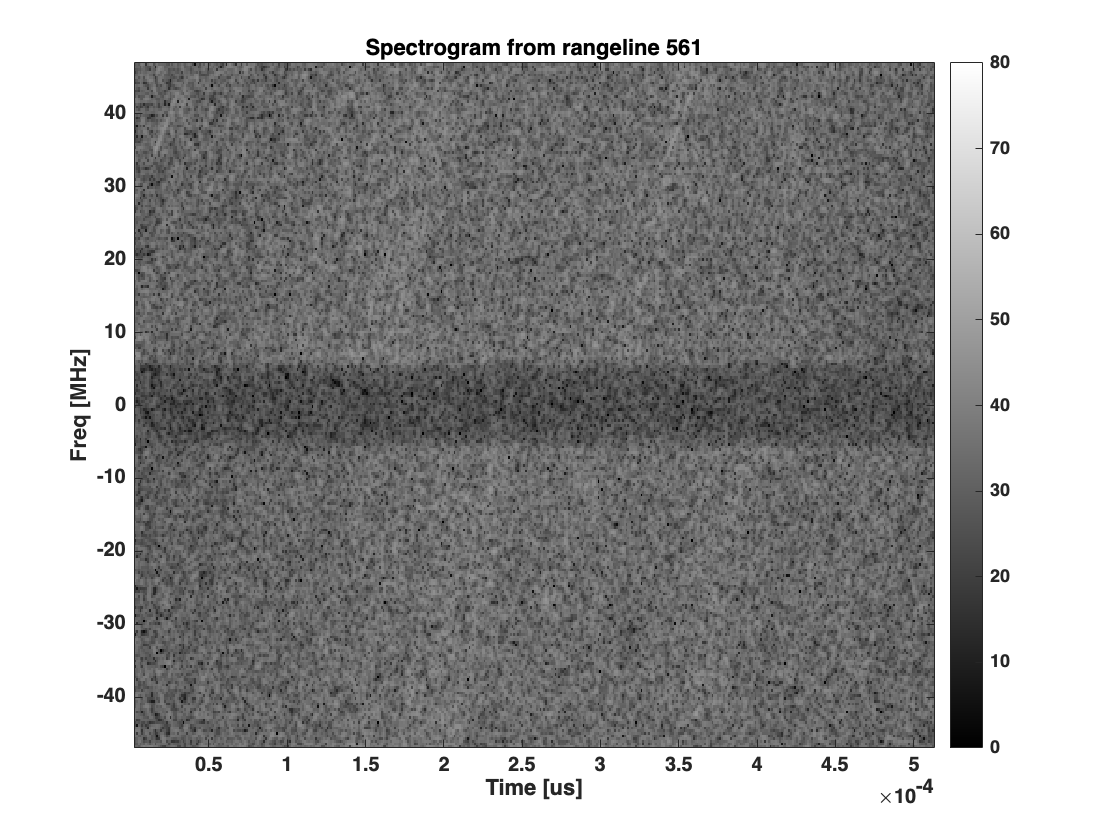

% Define spectrogram parameters
fs = 46918402.800000004;  
nfft = 256; 
window = hanning(nfft);  
noverlap = 200;  
row_idx = 561;  
fs_MHz = fs / 1e6;  
row_signal = radar_data(row_idx, :);

% Spectrogram
figure(11);
clf;
[S, F, T,P] = spectrogram(row_signal, window, noverlap, nfft, fs);  % In Hz
S_dB = 10 * log10(abs(S).^2);  
F = F / 1e6; 

% Plot centered around 0
F_centered = [-flipud(F(2:end)); F]; 
imagesc(T, F_centered, S_dB);  
colormap('gray');  
colorbar;

% Limits (dB scale)
clim([0, 80]); 

% Plot 
xlabel('Time [us]', 'FontWeight', 'bold');
ylabel('Freq [MHz]', 'FontWeight', 'bold');
title(['Spectrogram from rangeline ', num2str(row_idx)], 'FontWeight', 'bold');
set(gca, 'FontWeight', 'bold');
set(gca, 'YDir', 'normal'); 

**Creating simulated Chirp Signal**

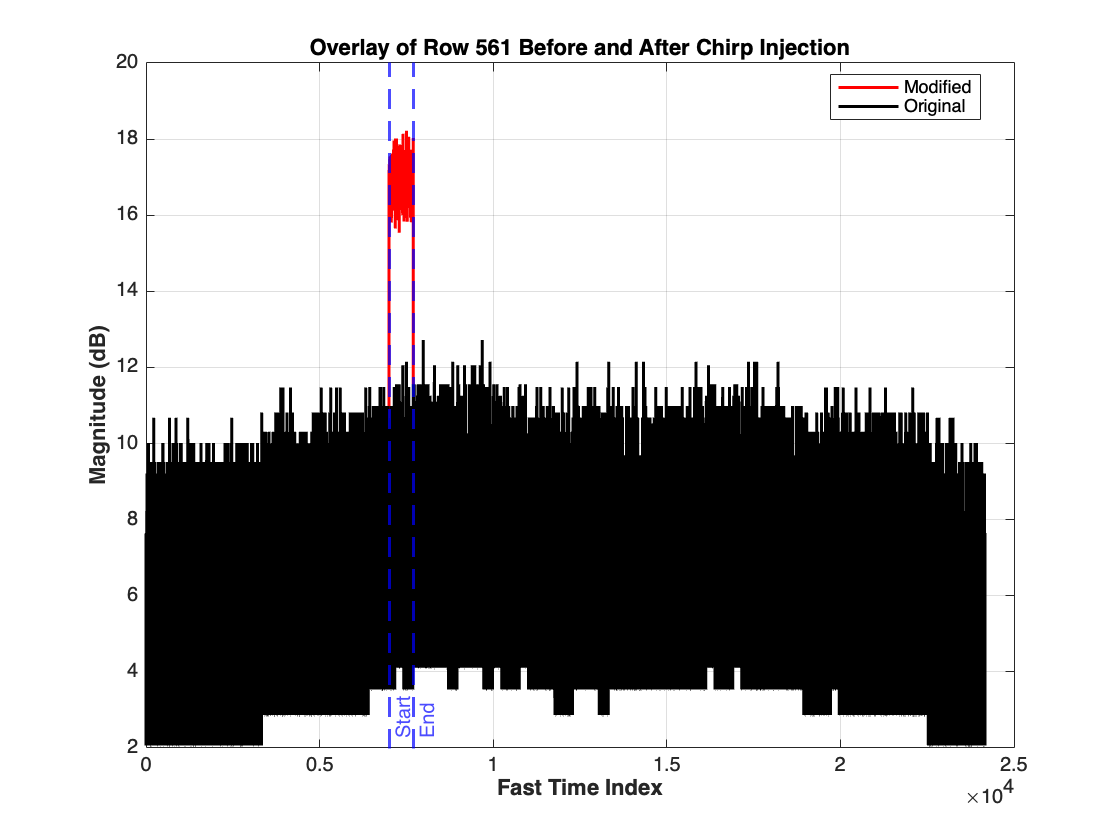

% Define chirp parameters
fs = 46918402.800000004; 
bw = 4.765e6; 
fc = -6.00e6;  
chirp_rate = 0.338e6 / 1e-6;  
start_idx = 7000;
end_idx = 7700;

% Start and end indices
T = (end_idx - start_idx + 1) / fs;
t = linspace(0, T, end_idx - start_idx + 1);  

% Generate linear chirp signal
chirp_signal = 50*exp(1j * (2 * pi * (fc * t + 0.5 * chirp_rate * t.^2)));

% Select a row 
row_idx = 561; 
num_cols = size(radar_data, 2);

% Comnparsion
radar_data_original = radar_data(row_idx, :);
chirp_signal_padded = zeros(1, num_cols);
chirp_signal_padded(start_idx:end_idx) = chirp_signal;  
radar_data(row_idx, :) = radar_data(row_idx, :) + chirp_signal_padded;
radar_data_modified = radar_data(row_idx, :);

% Original and modified 
figure;
plot(10 * log10(abs(radar_data_modified) + eps), 'r', 'LineWidth', 1.5);
hold on;
plot(10 * log10(abs(radar_data_original) + eps), 'k', 'LineWidth', 1.5); 
hold off;

% Chirp region
xline(start_idx, '--b', 'Start', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');
xline(end_idx, '--b', 'End', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');

xlabel('Fast Time Index', 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontWeight', 'bold');
title(['Overlay of Row ', num2str(row_idx), ' Before and After Chirp Injection'], 'FontWeight', 'bold');
legend({ 'Modified','Original'}, 'Location', 'Best');
grid on;

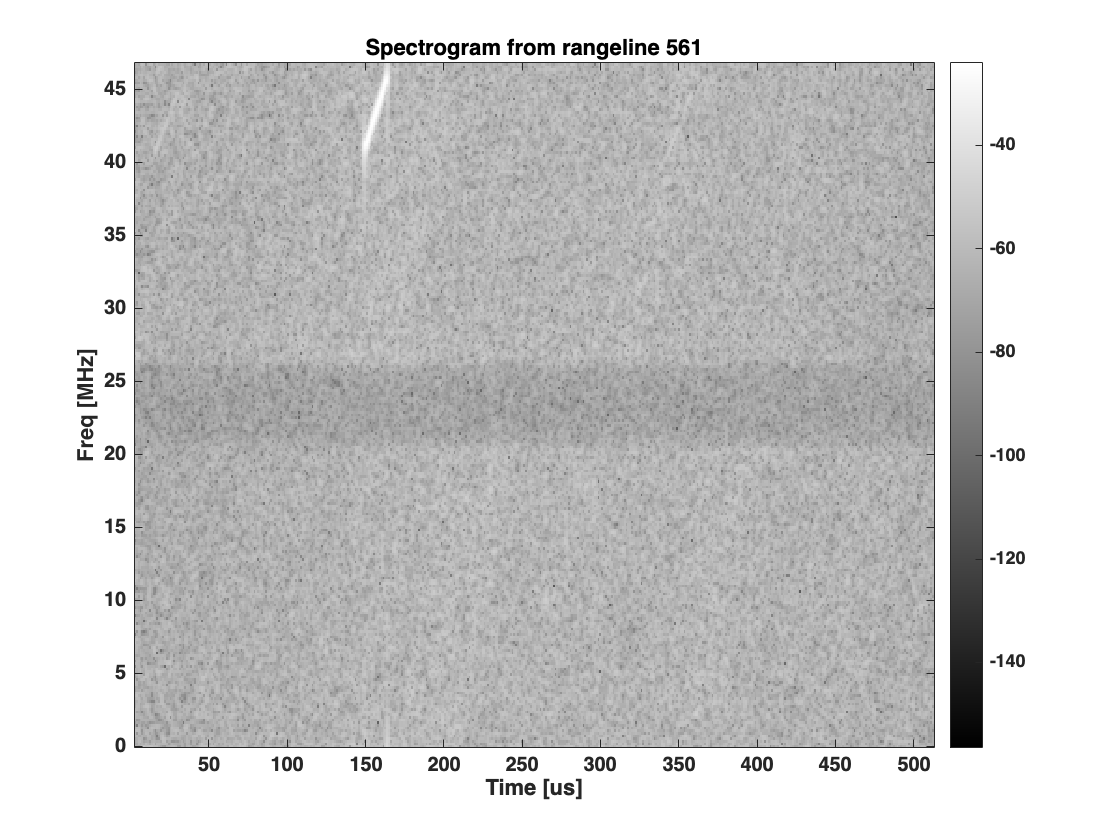



% Spectrogram parameters
nfft = 256;  
window = hanning(nfft);  
noverlap = 200; 
row_idx = 561; 

row_signal = radar_data(row_idx, :); 

% Spectrogram
figure(11);
clf;
spectrogram(row_signal, window, noverlap, nfft, fs, 'yaxis');

% Plot 
colormap('gray'); 
colorbar;
xlabel('Time [us]', 'FontWeight', 'bold');
ylabel('Freq [MHz]', 'FontWeight', 'bold');
title(['Spectrogram from rangeline ', num2str(row_idx)], 'FontWeight', 'bold');
set(gca, 'FontWeight', 'bold');
set(gca, 'YDir', 'normal');

Saving File

% Insert modified row back into radar_data
radar_data(row_idx, :) = radar_data_modified;

% Save the full modified radar_data
save('radar_data_modified.mat', 'radar_data');